# Analysis of Wind Turbine data -- Accleration

#### Dataset: D1C2SG1 -- Accleration labeled data 

**Description:** This dataset is from acclerometers in the tower area of the offshore Wind turbine.

#### Author: Vishu Sharma

#### Last Modified: 29.02.2023

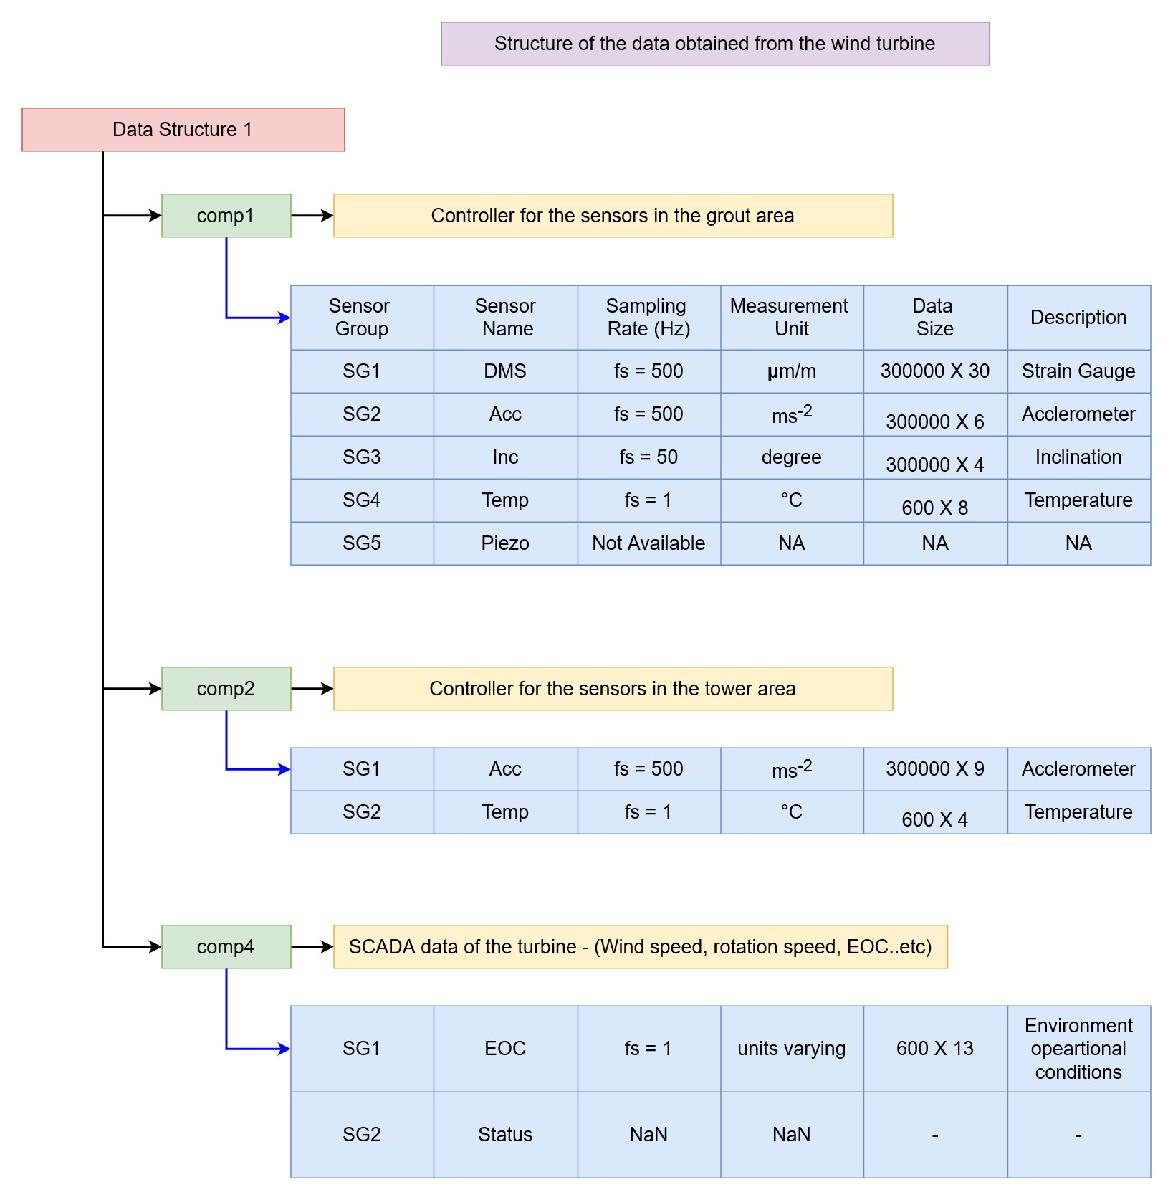

clear all, clc

% Loading data sets from CSV files

A = readmatrix("D:\University of Siegen\uos\research Project\Codes\Data\WT_labeled_data\D1C2SG1_Acc_Labeled.csv");

% Labeled variables for accleration signal 2

Acc2_z     = A(:,4);
Acc2_y     = A(:,5);
Acc2_x     = A(:,6);

% Constructing time vector 

Fs = 500;            % Sampling frequency
T = 1/Fs;            % Sampling period
L = 300000;          % length of signal
t = (0: L-1)*T;      % Time vector

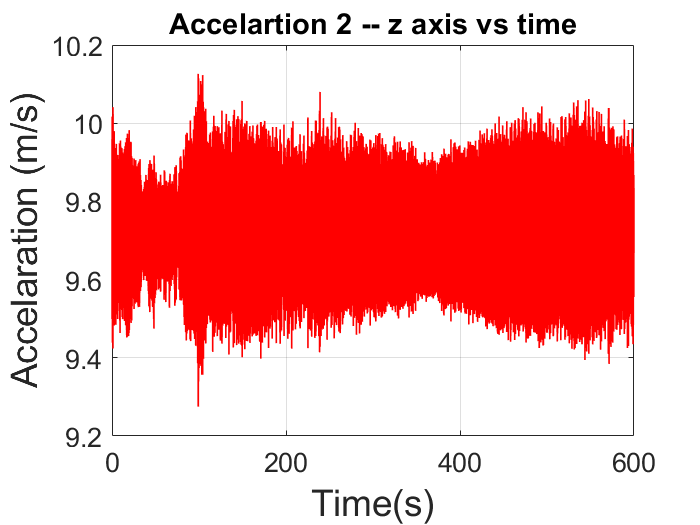

% Time Domain preliminary analysis -- Accelarations 2 z -axis

plot(t, Acc2_z, 'r','LineWidth',1)
title('Accelartion 2 -- z axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc2_z)

ans = 9.7264

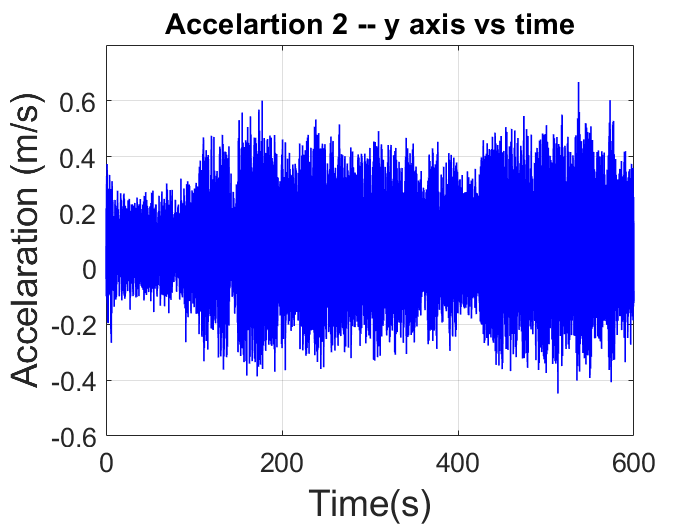

% Time Domain preliminary analysis -- Accelarations 2 y -axis

plot(t, Acc2_y, 'b','LineWidth',1)
title('Accelartion 2 -- y axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc2_y)

ans = 0.0777

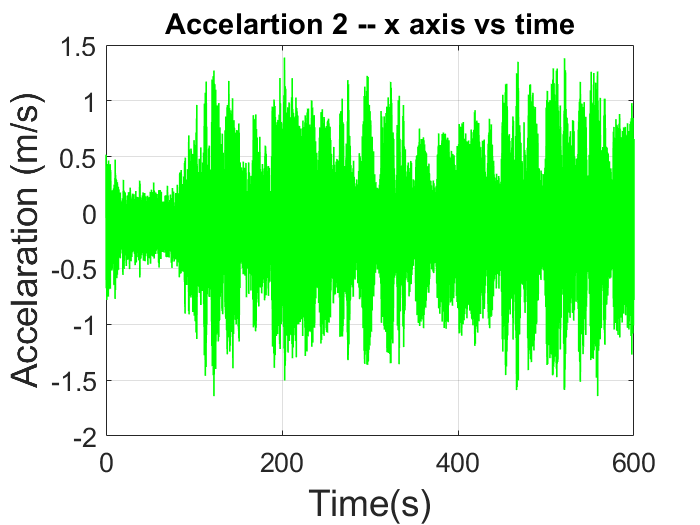

% Time Domain preliminary analysis -- Accelarations 2 x -axis

plot(t, Acc2_x, 'g','LineWidth',1)
title('Accelartion 2 -- x axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc2_x)

ans = -0.1179

% Zero mean values for accleration

ZM_Acc2_z = Acc2_z - mean(Acc2_z);
ZM_Acc2_y = Acc2_y - mean(Acc2_y);
ZM_Acc2_x = Acc2_x - mean(Acc2_x);

#### Fourier Spectral Analysis of accleration 2 signals

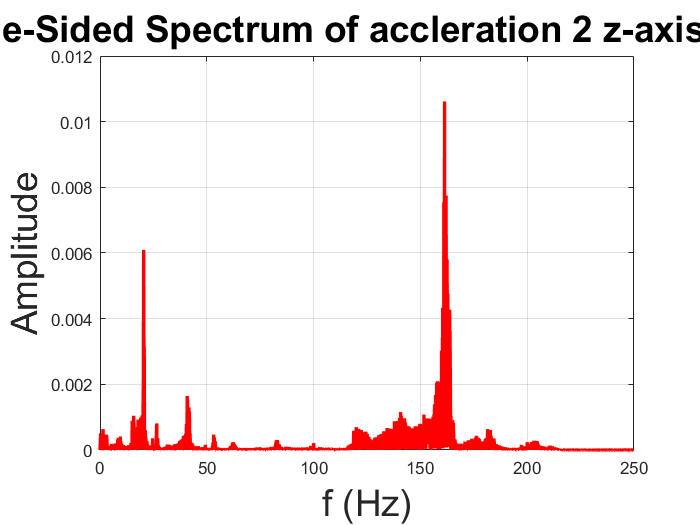

% Fourier Spectrum for z axis accleration - 2


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc2_z);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum of accleration 2 z-axis signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

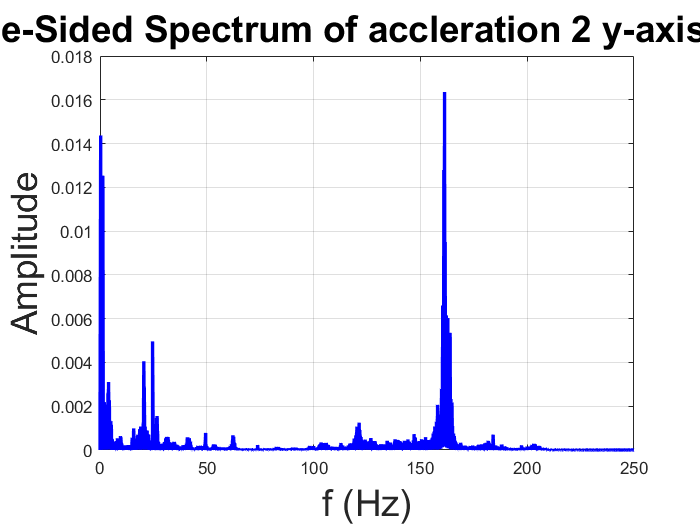

% Fourier Spectrum for y axis accleration - 2


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc2_y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'b','LineWidth',2) 

title('Single-Sided Spectrum of accleration 2 y-axis signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

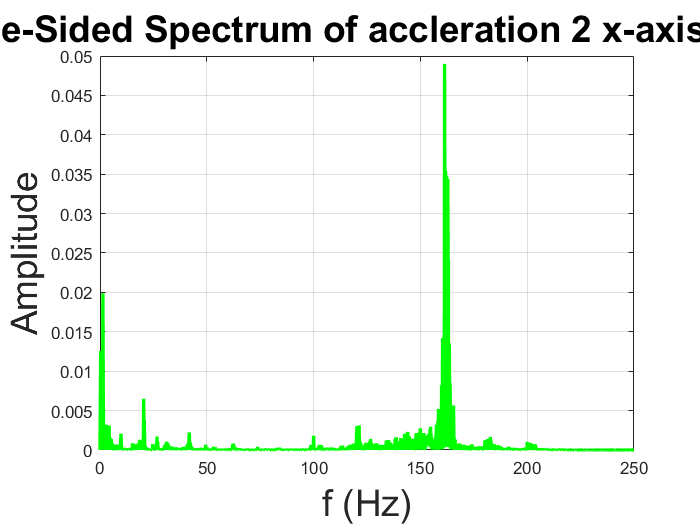

% Fourier Spectrum for x axis accleration - 2


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc2_x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'g','LineWidth',2) 

title('Single-Sided Spectrum of accleration 2 x-axis signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

#### Spectrograms for accleration 2 signals

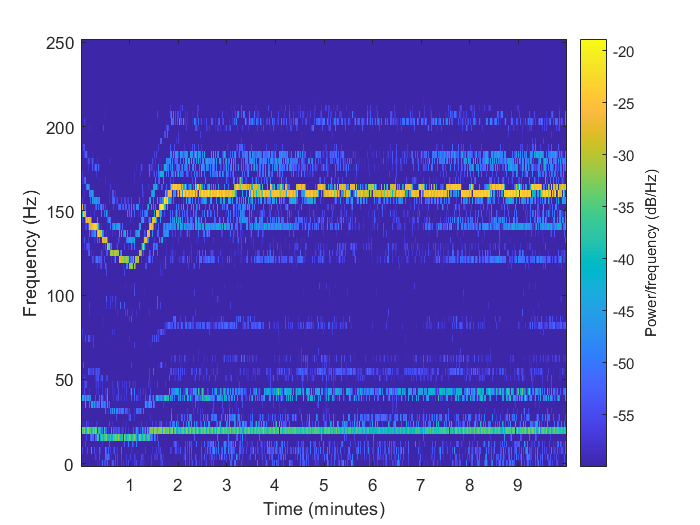

% Spectrogram for z-axis signal

s = spectrogram(ZM_Acc2_z);
spectrogram(ZM_Acc2_z, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

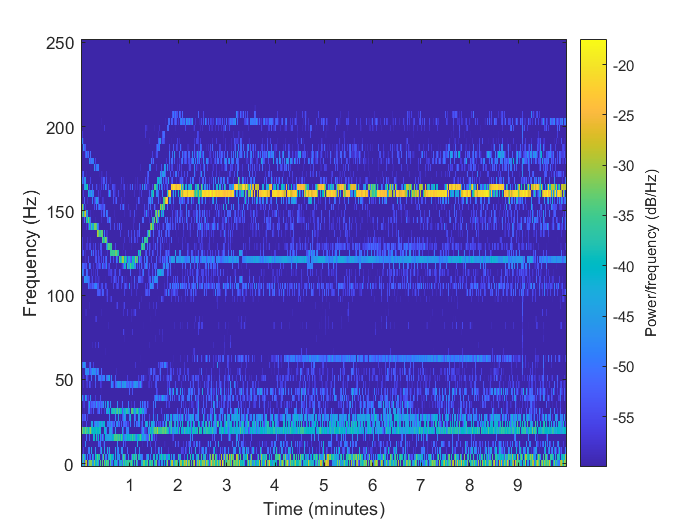

% Spectrogram for y-axis signal

s = spectrogram(ZM_Acc2_y);
spectrogram(ZM_Acc2_y, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

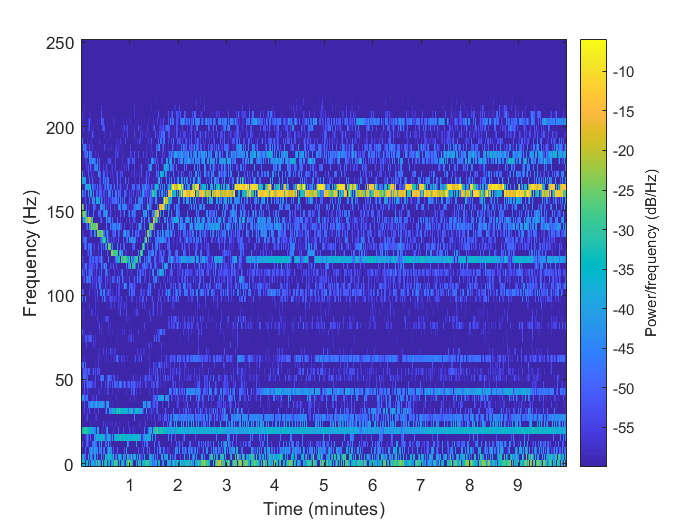

% Spectrogram for x-axis signal

s = spectrogram(ZM_Acc2_x);
spectrogram(ZM_Acc2_x, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

#### Hilbert Spectral Analysis for Accleration signal